# **静电型隐形衣演示**

**        《科学》杂志上报导的静电“隐身衣”，是一种双层柱状结构，中心圆柱采取完美金属构成，即介电常数**$\varepsilon_1$**为无穷大，任何电场都进入不到柱体内部。金属材料外部是一个内外半径分别为a和b的柱套，其介电常数为**$\varepsilon_2$**。当在背景材料中施加一个垂直于柱轴方向的匀强电场时，该电场不会受到任何扰动，就像背景材料中没有任何东西一样。**

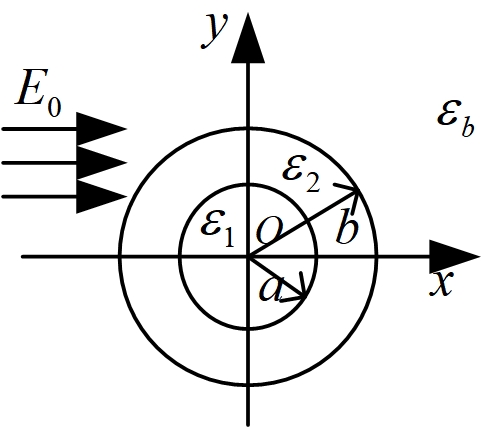    

**        对静电隐形装置的研究，可以使用柱坐标系下的分离变量开展。建立柱坐标系，假设各个区域中的电势分布如下**

  
$$\begin{array}{l}
\phi_1 =\textrm{Arcos}\varphi \\
\phi_2 =\left(\textrm{Br}+\frac{C}{r}\right)\cos \varphi \\
\phi_3 =\left(-E_0 r+\frac{D}{r}\right)\cos \varphi 
\end{array}$$


**        在介质的分界面上，有如下边界条件：**

**当**$r=a$**时，**$\phi_1 =\phi_2$**且**$\varepsilon_1 \frac{\partial }{\partial r}\phi_1 =\varepsilon_2 \frac{\partial }{\partial r}\phi_2$

**当**$r=b$**时，**$\phi_2 =\phi_b$**且**$\varepsilon_2 \frac{\partial }{\partial r}\phi_2 =\varepsilon_b \frac{\partial }{\partial r}\phi_b$

**        将各个区域的电势表达式代入，则有**

   
$$\begin{array}{l}
\textrm{Aa}=\textrm{Ba}+\frac{C}{a}\\
\varepsilon_1 A=\varepsilon_2 \left(B-\frac{C}{a^2 }\right)\\
\textrm{Bb}+\frac{C}{b}=-E_0 b+\frac{D}{b}\\
\varepsilon_2 \left(B-\frac{C}{b^2 }\right)=\varepsilon_b \left(-E_0 -\frac{D}{b^2 }\right)
\end{array}$$


**         写成矩阵方程的形式**


$$\left\lbrack \begin{array}{cccc}
a & -a & -\frac{1}{a} & 0\\
\varepsilon_1  & -\varepsilon_2  & \frac{\varepsilon_2 }{a^2 } & 0\\
0 & b & \frac{1}{b} & -\frac{1}{b}\\
0 & \mu_2  & -\frac{\varepsilon_2 }{b^2 } & \frac{\varepsilon_2 }{b^2 }
\end{array}\right\rbrack$$


**        利用MATLAB下的符号工具箱，可以求解上述四元一次方程组，假设有一需要隐身处理的是超导材料，即**$\varepsilon_1$**为无穷大，得到D的表达式为**


$$$$D = E _ { 0 } b ^ { 2 } \frac { a ^ { 2 } ( \varepsilon _ { b } + \varepsilon _ { 2 } ) + b ^ { 2 } ( \varepsilon _ { 2 } - \varepsilon _ { b } ) } { a ^ { 2 } ( \varepsilon _ { 2 } - \varepsilon _ { b } ) + b ^ { 2 } ( \varepsilon _ { 2 } + \varepsilon _ { b } ) }$$$$


**        如果要实现隐形的功能，则**$D=0$**，此时外部背景只有匀强磁场，于是**

$\varepsilon_2 =\frac{\left(b^2 -a^2 \right)}{\left(b^2 +a^2 \right)}\varepsilon_b$**或**${b^2 =a}^2 \frac{\varepsilon_2 +\varepsilon_b }{\varepsilon_b -\varepsilon_2 }$

**        假设半径a=0.2，介质柱套外的半径b=0.4，背景材料的介电常数为**$\varepsilon_b =1$**，计算可知柱套的介电常数为**$\varepsilon_2 =0\ldotp 6$**。**

**        下面为在PDETool中实现这个静磁隐身装置的具体步骤：**

- **在matlab的命令行，输入PDETool，进入图形界面**

- **选择应用模式为静电场模式--Electromagnetics；**

- **在绘图模式下，先后绘制矩形框R1和两个圆形E1和E2，双击标签修改尺寸和位置；**

- **在set formula中，设置公式为R1-E1+(E2-E1)；**

- **在边界条件模式下，设置矩形区域的上下两条边为齐次诺伊曼条件，矩形左右侧边界设为狄氏条件，左侧电势为5，右侧电势为0，从而在空间形成匀强电场，设置内部圆孔的边界为狄氏条件，电势值为2.5。**

- **在微分方程设置模式下，双击圆环区域，设置介电常数为0.6，电流密度为0；再双击矩形背景区域，设置介电常数为1，电流密度为0。**

- **单击网格生成图标，根据情况对其细化；**

- **单击求解按钮，即可得到电势分布的数值结果；**

**       定义参数：**

**超导柱半径：**

a=0.4;

**柱套层半径：**

b=0.6;

**计算可得柱套层的介电常数为：**

e2=(b^2-a^2)/(b^2+a^2)

e2 = 0.3846

**       用pdetool仿真：**

- **仅有超导柱时的电势分布仿真**

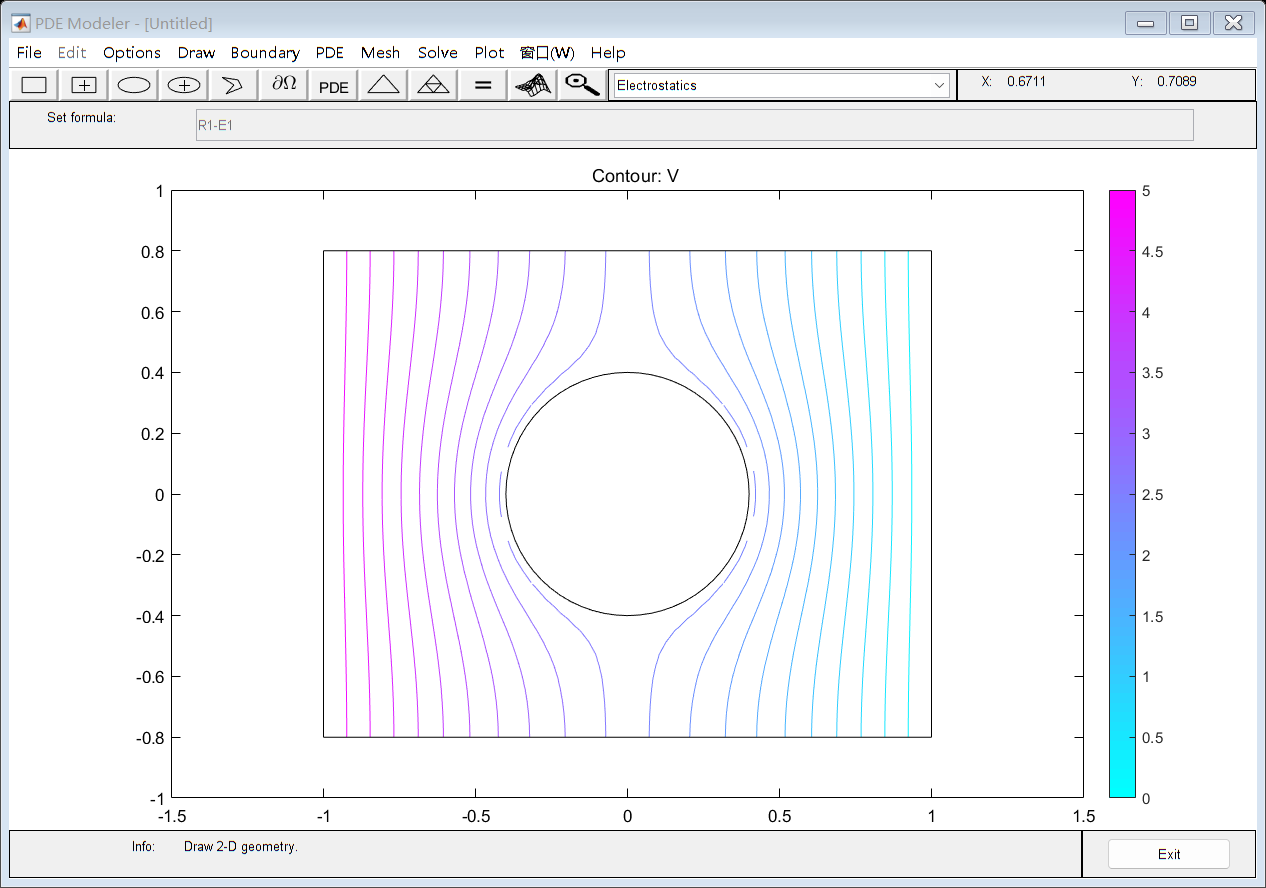

 Without_Invisibility_Cloak(a)

**        以上为空气中仅有超导柱的情况，可以看出，由于超导圆柱的存在，空间的电势分布都不再均匀。**

- **用隐形材料包裹超导柱时的电势分布**

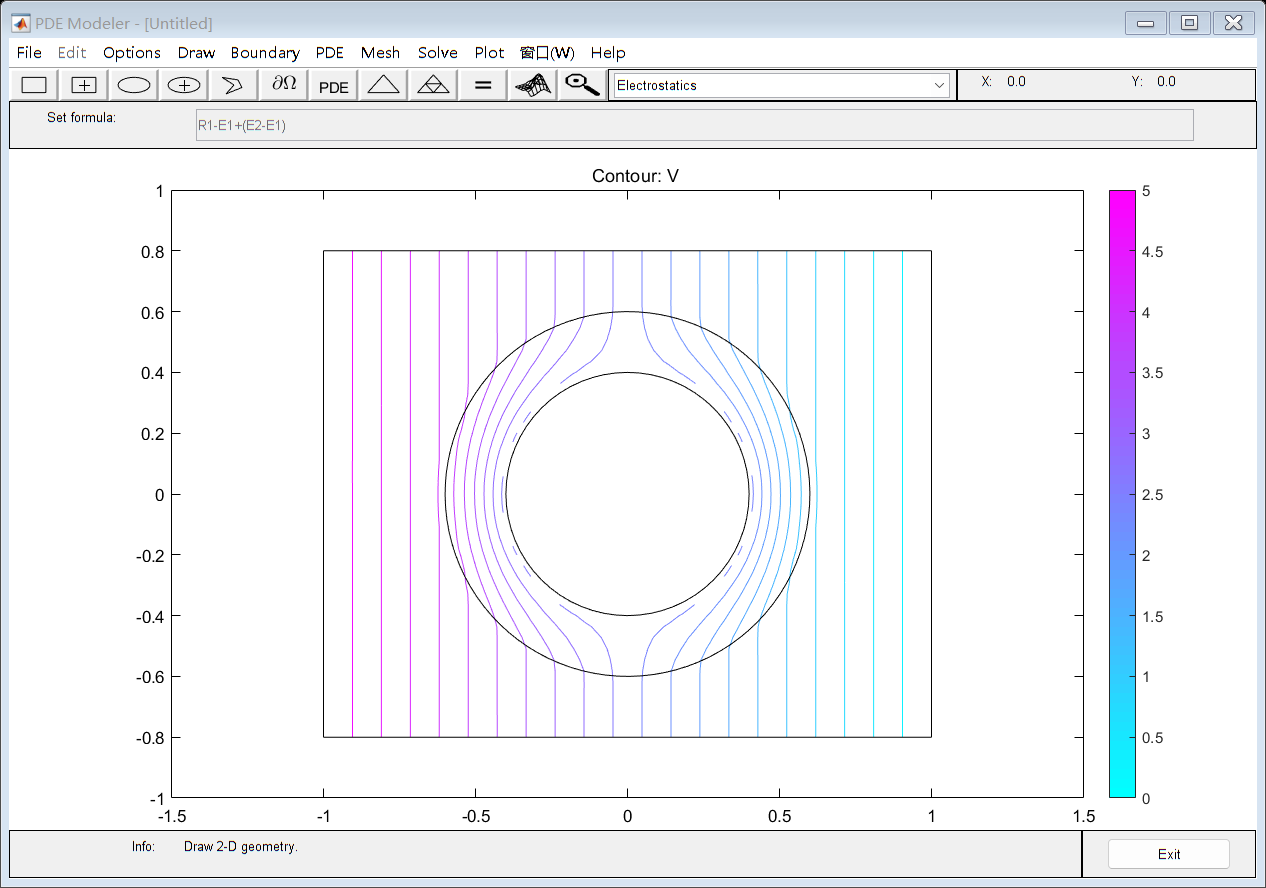

With_Invisibility_Cloak(a,b,e2)

**        当采用了隐形材料包裹超导柱之后，空间背景中的电势分布又变得均匀，所有扰动都发生在柱套内部。因此，达到了在静电场中隐形的目的。**

- **使用PDETool仿真生成的函数**

function  With_Invisibility_Cloak(a,b,e2)
    e=['1.0!', num2str(e2)];
    current_density='0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(e) - length(current_density))];

    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,a,a,...
    0,'E1');
    pdeellip(0,0,b,b,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1+(E2-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.50')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    e,...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [e;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6144','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end
function  Without_Invisibility_Cloak(a)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,a,a,...
    0,'E1');

    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.50')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0!1',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!1';...
    '0!0  '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6144','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end